
=== Running Experiment 1 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.1000
    mb: 256


    mm: 'sgdm'
    lr: 0.1000
    mb: 256




=== Running Training 1 ===

=== Done Training 1 ===


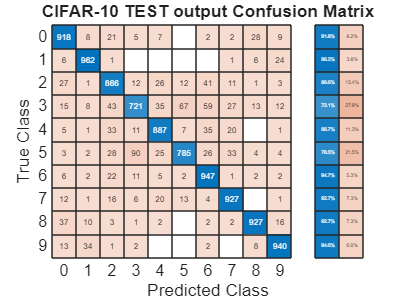

Overall Accuracy (from CM): 88.8%


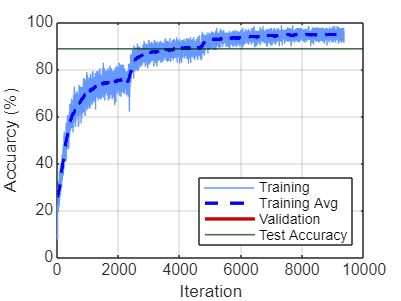

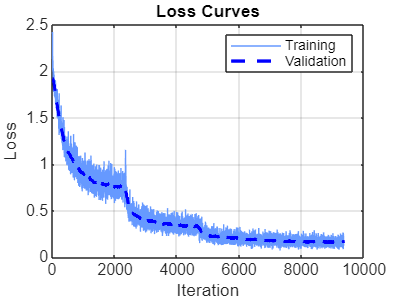


=== Running Experiment 2 ===


cfg = struct with fields:
    mm: 'adam'
    lr: 1.0000e-03
    mb: 128


    mm: 'adam'
    lr: 1.0000e-03
    mb: 128




=== Running Training 2 ===

=== Done Training 2 ===


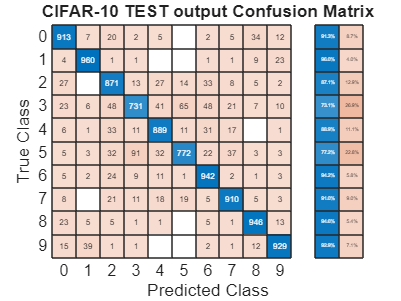

Overall Accuracy (from CM): 88.63%


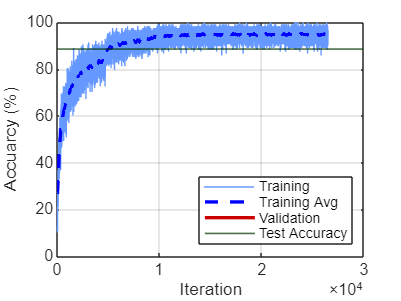

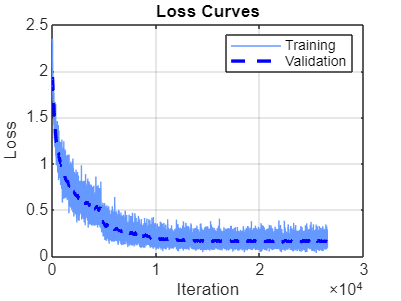


=== Running Experiment 3 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.0100
    mb: 64


    mm: 'sgdm'
    lr: 0.0100
    mb: 64




=== Running Training 3 ===

=== Done Training 3 ===


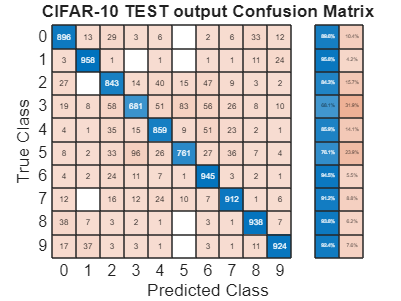

Overall Accuracy (from CM): 87.17%


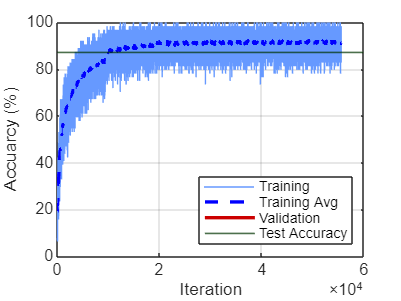

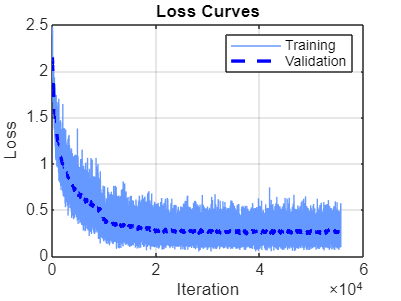


=== Running Experiment 4 ===


cfg = struct with fields:
    mm: 'rmsprop'
    lr: 1.0000e-03
    mb: 128


    mm: 'rmsprop'
    lr: 1.0000e-03
    mb: 128




=== Running Training 4 ===

=== Done Training 4 ===


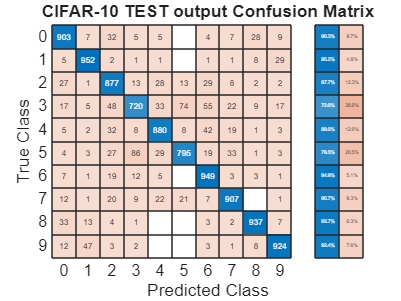

Overall Accuracy (from CM): 88.44%


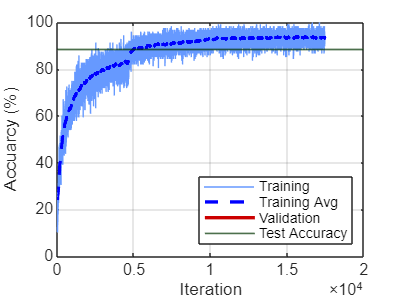

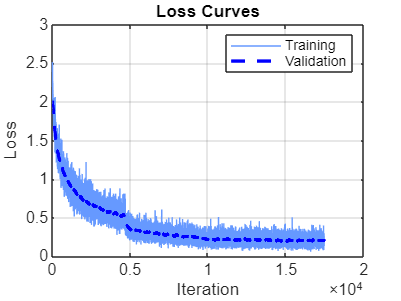


=== Running Experiment 5 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.0100
    mb: 128


    mm: 'sgdm'
    lr: 0.0100
    mb: 128




=== Running Training 5 ===

=== Done Training 5 ===


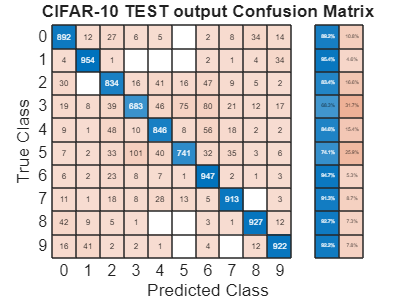

Overall Accuracy (from CM): 86.59%


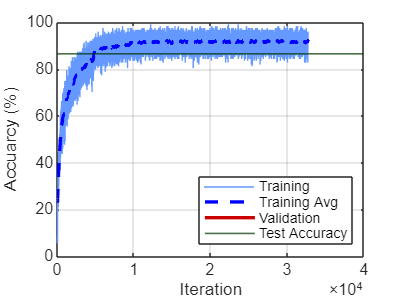

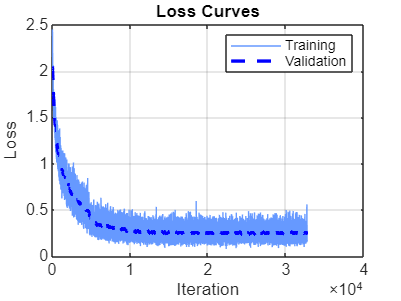


=== Running Experiment 6 ===


cfg = struct with fields:
    mm: 'rmsprop'
    lr: 0.0100
    mb: 64


    mm: 'rmsprop'
    lr: 0.0100
    mb: 64




=== Running Training 6 ===

=== Done Training 6 ===


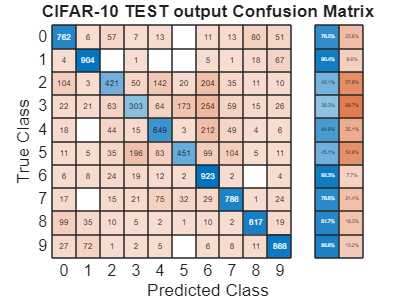

Overall Accuracy (from CM): 68.84%


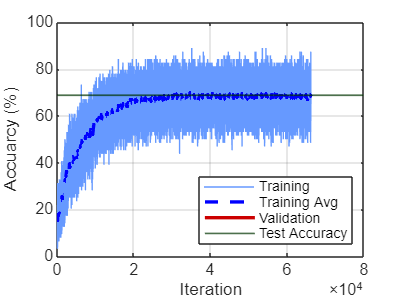

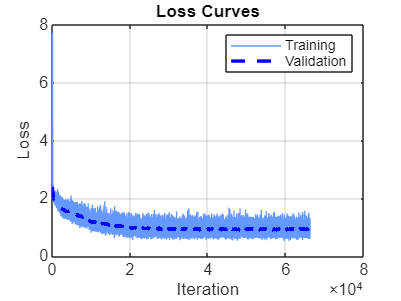


=== Running Experiment 7 ===


cfg = struct with fields:
    mm: 'rmsprop'
    lr: 1.0000e-03
    mb: 256


    mm: 'rmsprop'
    lr: 1.0000e-03
    mb: 256




=== Running Training 7 ===

=== Done Training 7 ===


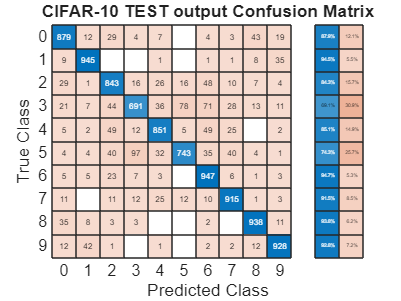

Overall Accuracy (from CM): 86.8%


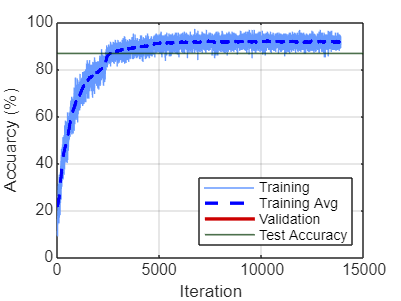

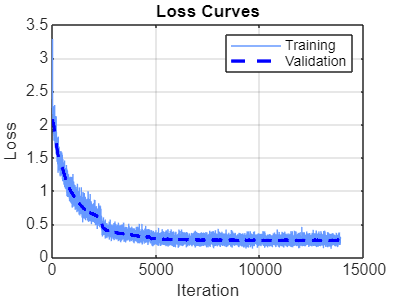


=== Running Experiment 8 ===


cfg = struct with fields:
    mm: 'adam'
    lr: 1.0000e-03
    mb: 256


    mm: 'adam'
    lr: 1.0000e-03
    mb: 256




=== Running Training 8 ===

=== Done Training 8 ===


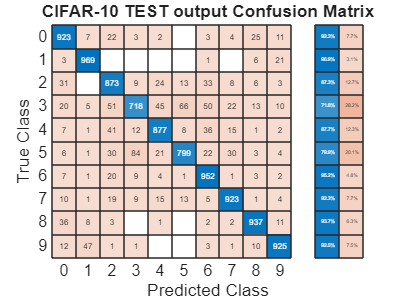

Overall Accuracy (from CM): 88.96%


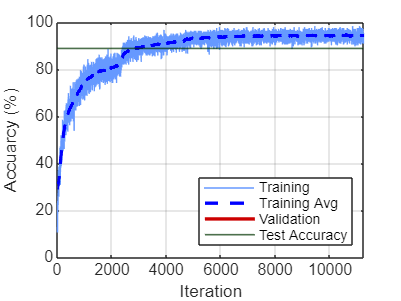

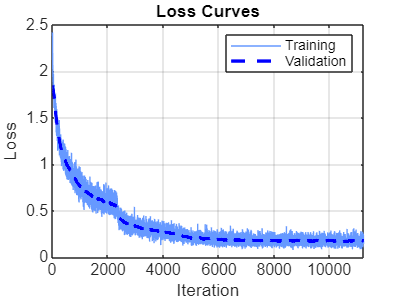


=== Running Experiment 9 ===


cfg = struct with fields:
    mm: 'sgdm'
    lr: 0.0100
    mb: 256


    mm: 'sgdm'
    lr: 0.0100
    mb: 256




=== Running Training 9 ===


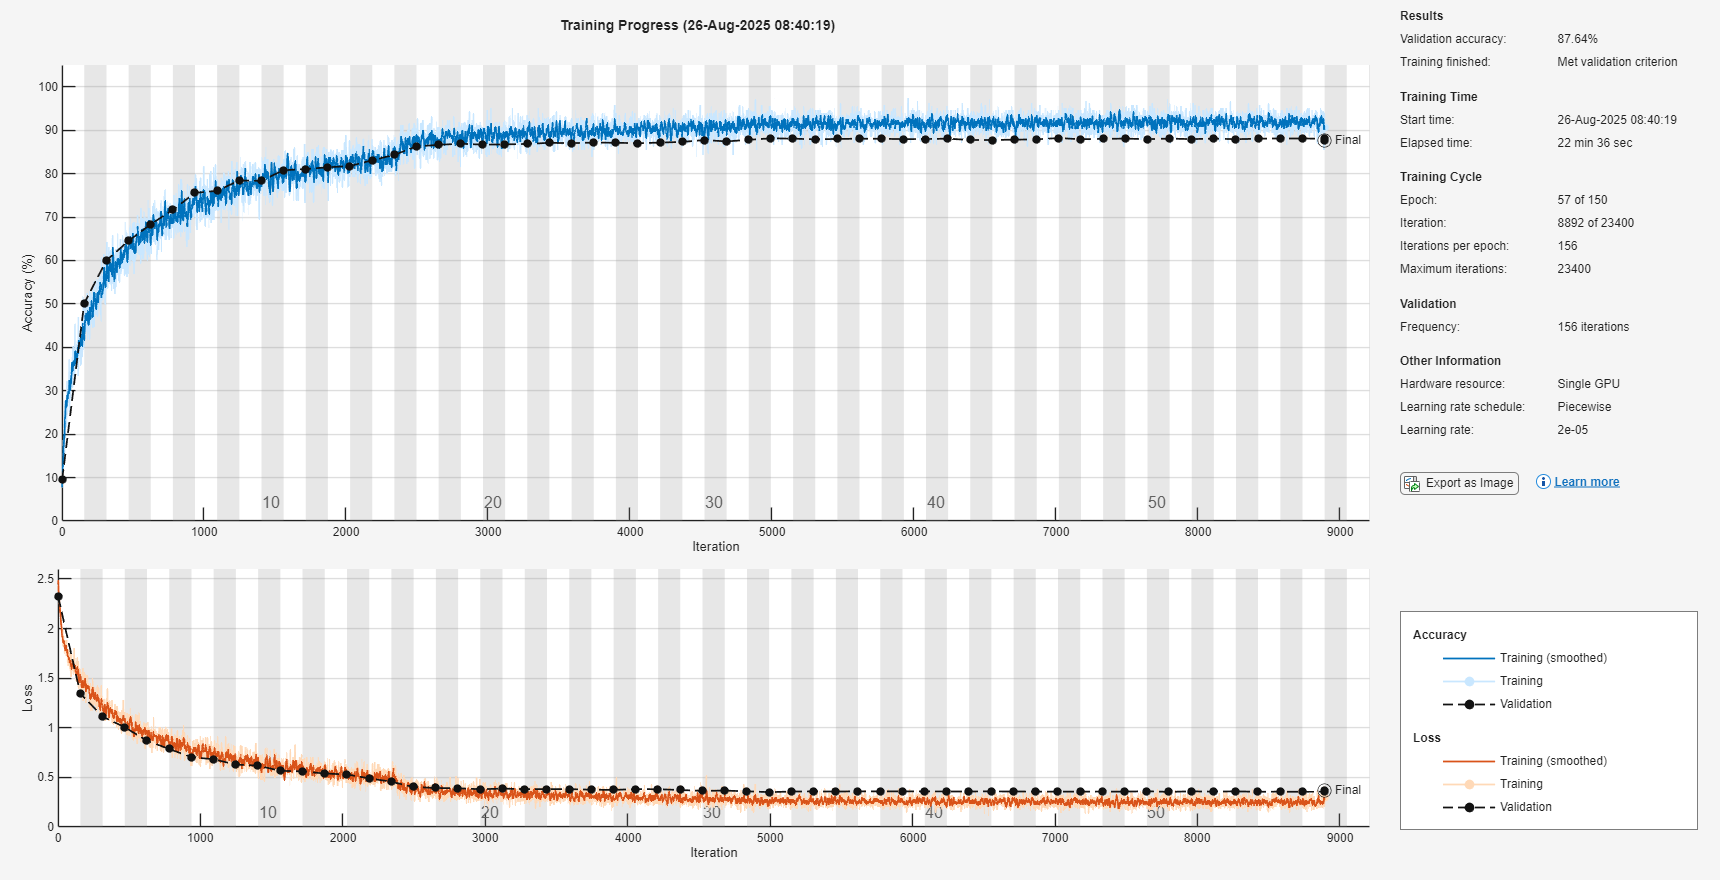


=== Done Training 9 ===


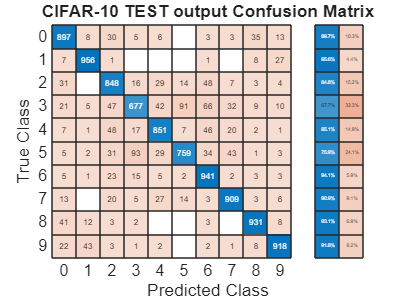

Overall Accuracy (from CM): 86.87%


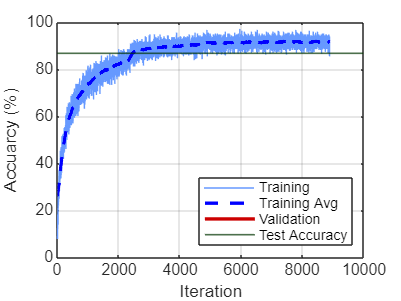

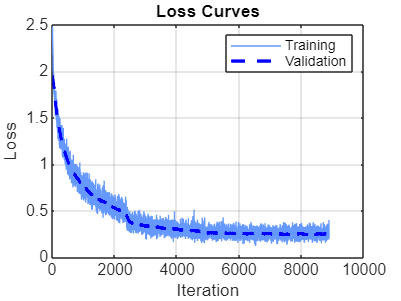

clearvars
global options
% Define ranges
configs = [
    struct('mm','sgdm','lr',0.01,'mb',128),...
    struct('mm','sgdm','lr',0.1,'mb',128),...
    struct('mm','sgdm','lr',0.1,'mb',256),...    
    struct('mm','adam','lr',0.001,'mb',128),...
    struct('mm','sgdm','lr',0.01,'mb',64),...
    struct('mm','rmsprop','lr',0.001,'mb',128),...
    struct('mm','sgdm','lr',0.01,'mb',128),...
    struct('mm','rmsprop','lr',0.01,'mb',64),...
    struct('mm','rmsprop','lr',0.001,'mb',256),...
    struct('mm','adam','lr',0.001,'mb',256),...
    struct('mm','sgdm','lr',0.01,'mb',256),...
    ];

loadtrainingdata
co = 5;
for expNum = 1:length(configs)
    fprintf('\n=== Running Experiment %d ===\n', expNum);
    clearvars -except configs co mm  ...
        options expNum ...
        trainImages valImages testImages ...
        trainLabels valLabels testLabels ...
        imageAugmenter trainDS valDS testDS 
    
    cfg = configs(expNum)
    mm = cfg.mm;
    disp(cfg)
    createTrainingOptions(cfg.mm,cfg.lr*cfg.mb/128,15,150,cfg.mb,valDS,floor(size(trainImages,4)/cfg.mb),0.9,true);
    conv5layers
    runfile
end